Algorithm for the numerical approx of $F(\nu_k)$ 

pf=@(x) exp(-2*abs(x)); % Exponential function
T=2*pi; N=16; %Tj in [-T/2; T/2] 

tj= T/N * (-N/2:N/2);
fj =pf(tj); %Equispaced Input Samples

% 1. Define the vector of samples
f0 = (fj(1)+fj(end))/2;
f = [f0 fj(2:end-1)];

% 2. Compute the fft
F = fft(f);
%3. Reorder the vector
F = fftshift(F)

F =     0.3730   -0.3871    0.4268   -0.5098    0.6546   -0.9240    1.4041   -2.1718    2.6711   -2.1718    1.4041   -0.9240    0.6546   -0.5098    0.4268   -0.3871



%4. Add the last component and the scale factors
F = [F F(1)]*T/N 

F =     0.1465   -0.1520    0.1676   -0.2002    0.2570   -0.3628    0.5514   -0.8529    1.0489   -0.8529    0.5514   -0.3628    0.2570   -0.2002    0.1676   -0.1520    0.1465


F(2:2:end)= -F(2:2:end) % Change the sign to the even elements

F =     0.1465    0.1520    0.1676    0.2002    0.2570    0.3628    0.5514    0.8529    1.0489    0.8529    0.5514    0.3628    0.2570    0.2002    0.1676    0.1520    0.1465



%5. Compute the frequencies
nu=(-N/2:N/2)/T % compute nu

nu =    -1.2732   -1.1141   -0.9549   -0.7958   -0.6366   -0.4775   -0.3183   -0.1592         0    0.1592    0.3183    0.4775    0.6366    0.7958    0.9549    1.1141    1.2732



%% IFT (same algorithm for Fourier Synthesis Series)
G=F(1:end-1) %F minus the components we added

G =     0.1465    0.1520    0.1676    0.2002    0.2570    0.3628    0.5514    0.8529    1.0489    0.8529    0.5514    0.3628    0.2570    0.2002    0.1676    0.1520


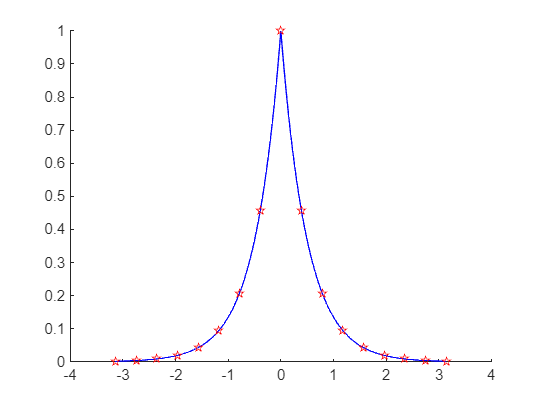

G(2:2:end) = -G(2:2:end); %Change again the sign of even el.
g=ifft(fftshift(G));
g=[g g(1)]/T*N;

% Plot the Results
x=linspace(-T/2,T/2,499); y=pf(x); %The function

%Reconstructed signal and original function
hold on;
plot(x,y,'b');
plot(tj,real(g),'pr');
hold off;

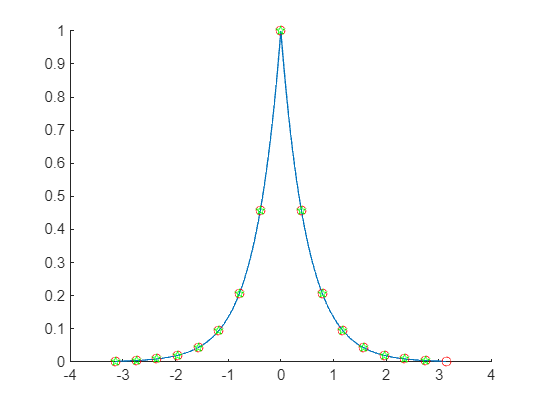


%Plot of (tj,fj) and tj minus the last elemnt and fj
clf; hold on;
plot(x,y); %Original function
plot(tj,fj,'ro'); % equispaced samples
plot(tj(1:end-1),f,'gp');
hold off;

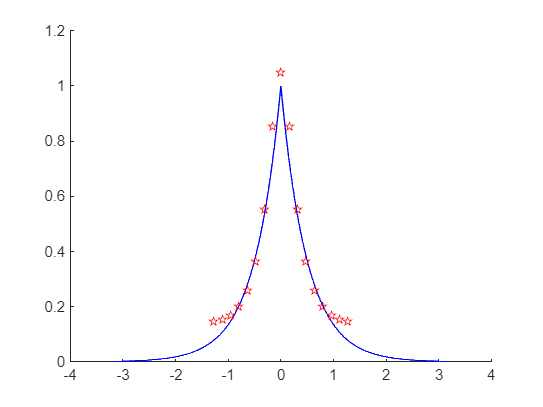


% The frequency nu and F
clf; hold on; 
plot(x,y,'b');
plot(nu,abs(F),'rp'); 
hold off;

Comparison with the symbolic

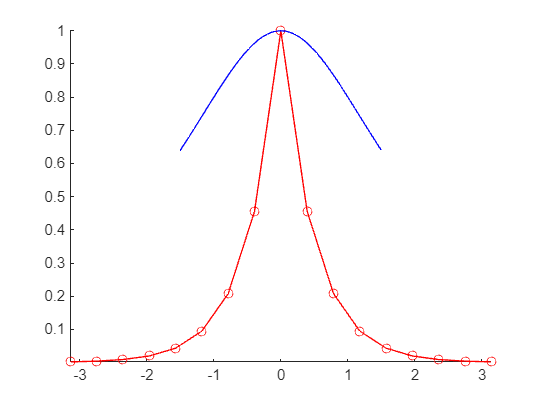

syms t real; Fw=fourier(sym(pf));

%Completely Wrong Plot:
clf; hold on; 
plot(tj,fj,'r-o');
fplot(abs(Fw),[-1.5,1.5],'blue')
axis tight;
hold off;


%How to fix
syms w v real, O=N/T

O = 2.5465

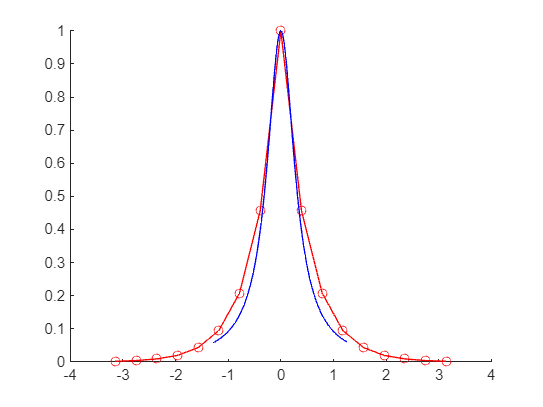

Fv=subs(Fw,w,2*pi*v); %since omega=2*pi*v
clf; hold on;
plot(tj,fj,'r-o');
fplot(abs(Fv),[-O/2,O/2],'blue')
hold off;

## Application 1: remove noise

dt=.005

dt = 0.0050

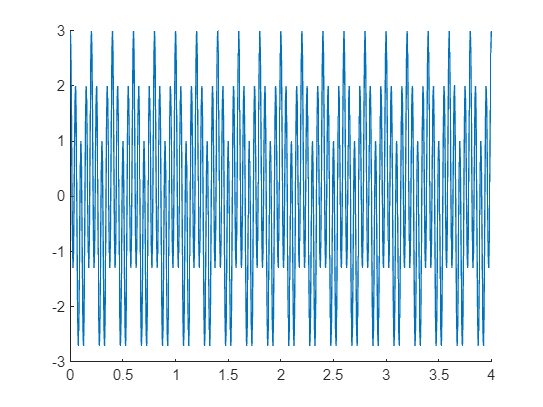

t=(0:dt:4)';
N=numel(t)-1;
T=4;

%Fj is an input signal that contains
%2 waves of frequency 5 and 20
fj = cos(2*pi*5*t) + 2*cos(2*pi*20*t);
clf; hold on;
plot(t,fj); 
axis([0 4 -3 3]);
hold off

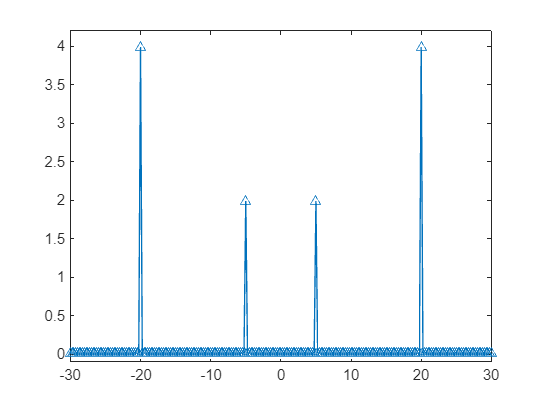


f=[0.5*fj((1)+fj(end)); fj(2:end-1)];
F = fftshift(fft(f));
F=[F;F(1)]*T/N;
F(2:2:end)=-F(2:2:end);

%Compute frequency
nu=(-N/2:N/2)'/T;

%The two external lines represent 2*cos(2*pi*20*t)
% The two INTERNAL lines represent cos(2*pi*5*t)
figure; plot(nu,abs(F),'^-'); axis([-30 30 -.1 4.2])

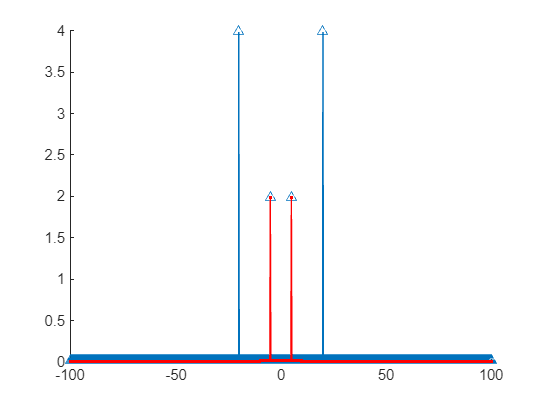



%Application of a Low Pass filter
%|v| > W/2=10 are set to 0

G=zeros(size(F)); 
k=find(abs(nu)<10); %Find frequencies < 10
G(k)=F(k); %Application of the filter

%The plot shows the filter window
figure; hold on;
plot(nu,abs(F),'^-');
plot(nu,abs(G),'r.-');
hold off;

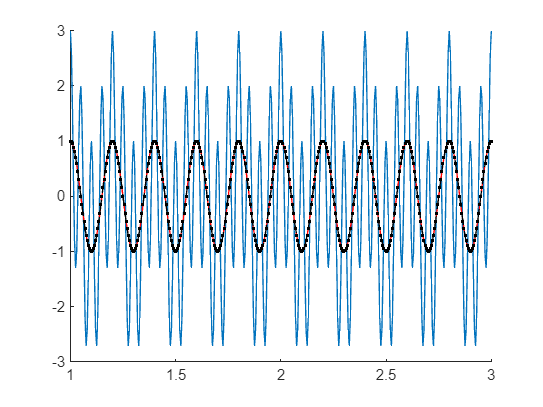


%Get the result of the filter in the time domain
H=G(1:end-1); H(2:2:end)=-H(2:2:end);
h=ifft(fftshift(H));
h=[h;h(1)]/T*N;

figure; hold on;
plot(t,fj);
plot(t,real(h),'r'); %plot of IFT(G)
plot(t,cos(2*pi*5*t),'.k--'); %the first component
axis([1 3 -3 3])
hold off;

## Application 2

Find the periodicity of equispaced data of "El Ninho"

load ninho
N=numel(fj);

tj=(0:N-1)'/12 + 1950; % time in year
%12: months

display(tj) 

tj = 1.0e+03 *

    1.9500
    1.9501
    1.9502
    1.9503
    1.9503
    1.9504
    1.9505
    1.9506
    1.9507
    1.9507


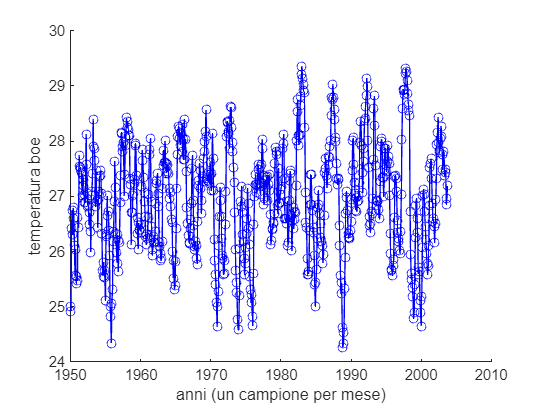


clf; figure; hold on;
plot(tj,fj,'b-o'); 
ylabel('temperatura boe');
xlabel('anni (un campione per mese)')
hold off;


% Divide the data 1 sample per month
T=tj(end)-tj(1);
Dt = T/N 

Dt = 0.0832

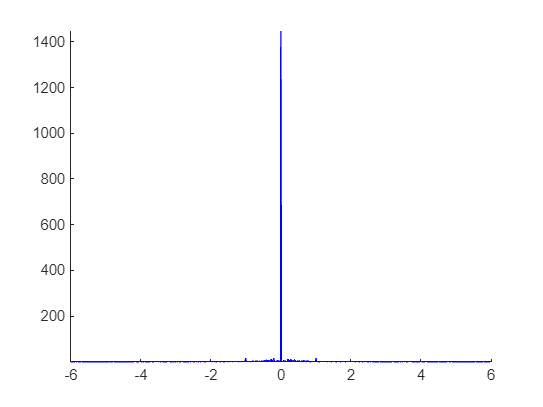

Dnu=1/T;
nu=(-N/2:N/2)'*Dnu;

%Apply the FFT
F= fftshift(fft(fj)); 
F=[F; F(1)]*T/N;
F(1:2:end)=-F(1:2:end);
%^ this time when changin the sign
%we consider the odd elemnts

figure; hold on;
plot(nu,abs(F),'b'); axis tight;
hold off;

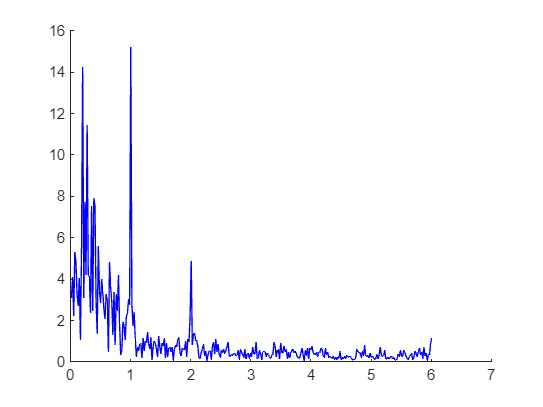


%Consider only positive frequencies
mid=N/2+2; 
figure; hold on;
plot(nu(mid:end),abs(F(mid:end)),'b');
hold off;

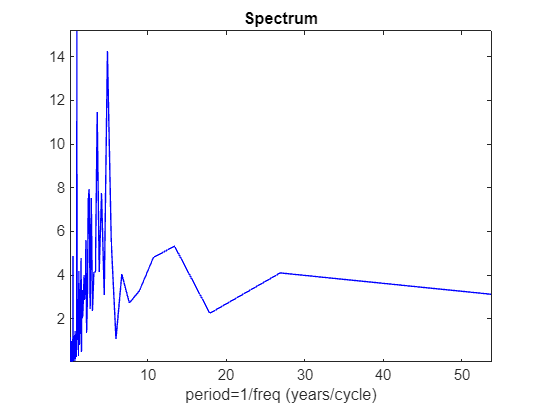


%Instead of frequencies, consider periods in year:
period=1./nu(mid:end);
figure; plot(period,abs(F(mid:end)),'b'); axis tight;
xlabel('period=1/freq (years/cycle)'); title('Spectrum');

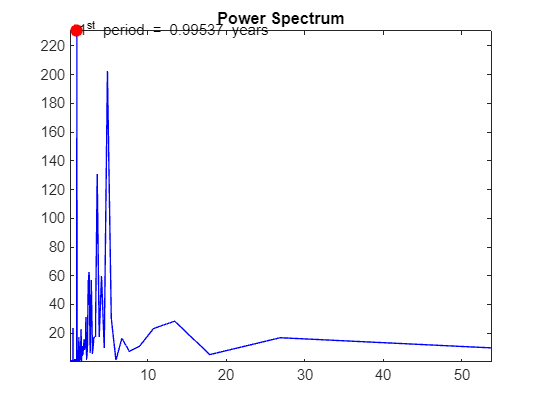


power = abs(F(mid:end)).^2;
figure;
plot(period,power,'b'); axis tight;
title('Power Spectrum');  hold on;
%Temperature repeats cyclically every year


%%find the index of the 1st maximum in the Power Spectrum
index=find(power == max(power));
p1=period(index);
plot(p1,power(index),'r.','MarkerSize',25);
text(period(index),power(index),['1^{st} period = ' num2str(period(index)) ' years']);

## Application 3 Dual-Tone multi-frequency DTMF phone keypad

info=audioinfo('Phone_Num\PhoneNumber.wav');
[y,fs]=audioread('Phone_Num\PhoneNumber.wav');
%sound(y,fs);

display(y);

y =          0
    0.2164
    0.4217
    0.6052
    0.7576
    0.8715
    0.9413
    0.9642
    0.9398
    0.8703


display(fs); %Frequency

fs = 32768

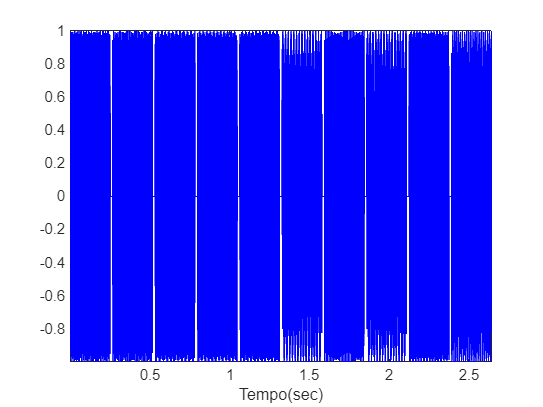


%Same as before
N=numel(y);
Dt=1/fs; 
tj = Dt*(1:N)';
T=N*Dt;

figure(1); plot(tj,y,'b'); axis tight; xlabel('Tempo(sec)');

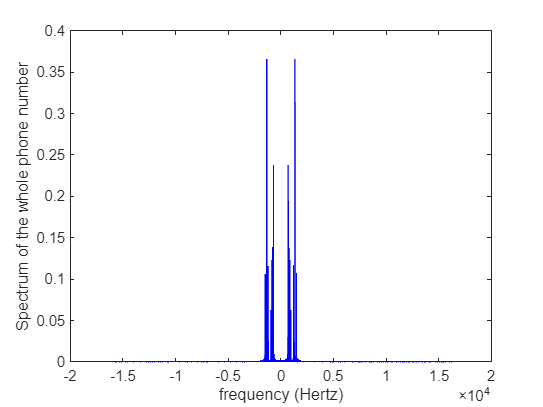


Y=fftshift(fft(y)); Y=[Y; Y(1)]*T/N; Dnu=1/T; 
nu=(-N/2:N/2)'/T;

figure(2); plot(nu,abs(Y),'b');
xlabel('frequency (Hertz)'); ylabel('Spectrum of the whole phone number');

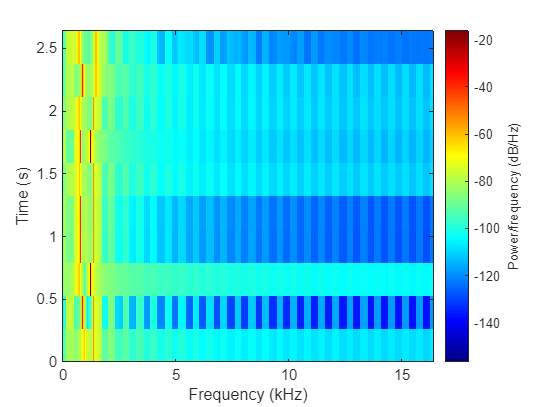


%We need to apply the Short Time Fourier Transform
M=fix(numel(y)/10);
spectrogram(y,M,0,[],fs);
colormap('jet');

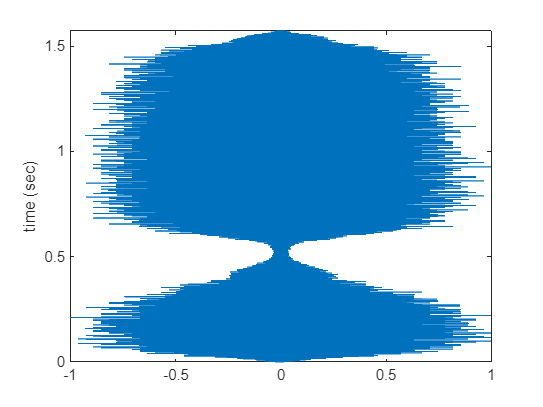

load train.mat
sound(y,Fs) 
Dt=1/Fs;
N=numel(y);

Duration = Dt*N;
tj=linspace(0,Duration,N);

figure; plot(y,tj); axis tight; ylabel('time (sec)')

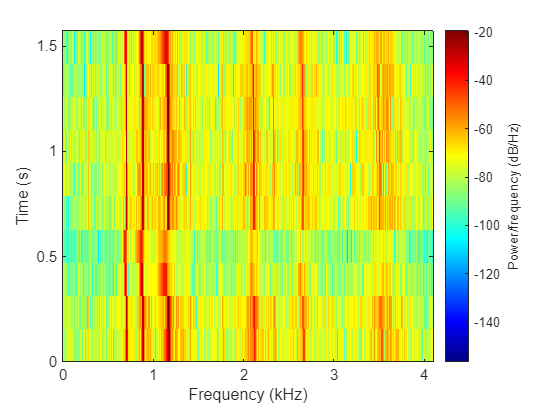

M=fix(N/10); spectrogram(y,M,0,[ ], Fs); colormap('jet')

## Application to Music

Experiment with Piano

%Example: reconstruction of pure sound
[y,fs]=audioread('audio_files\PIANO.WAV')

y =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


fs = 44100

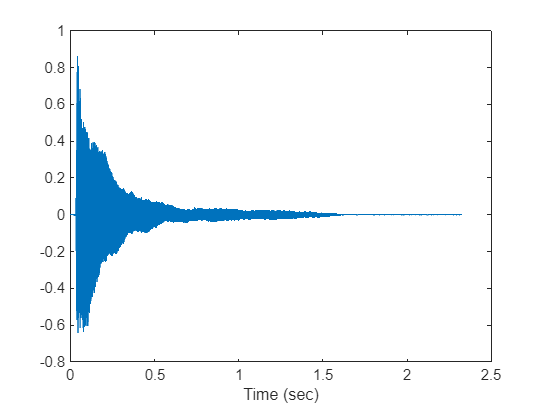

sound(y,Fs);

N=numel(y); Dt=1/fs; tj=Dt*(1:N)'; T=N*Dt; Dnu=1/T;

figure(1); plot(tj,y); xlabel('Time (sec)');

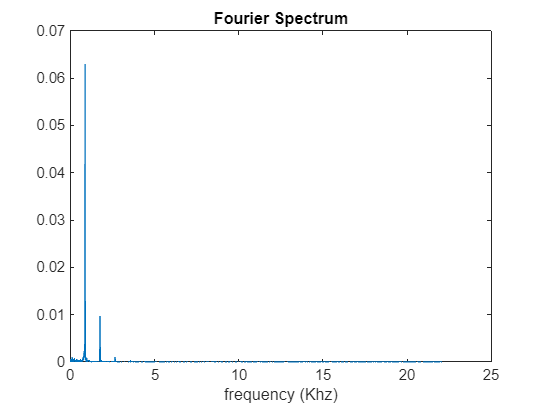


Y=fftshift(fft(y)); Y=[Y; Y(1)]*T/N;
nu=(-N/2:N/2)'/T;

m=N/2+1;

figure(2), plot(1e-3*nu(m:end),abs(Y(m:end))) %Khz
xlabel('frequency (Khz)'); title('Fourier Spectrum')


power = abs(Y(m:end)).^2;
%1st maximum
index=find(power == max(power));
note_Khz = nu(m+index)

note_Khz = 878.3181


display([note_Khz*1e-3])

    0.8783



Repeat the experiment but with a violin and notice how we have have sever frequencies vibrating at once.

[y,fs]=audioread('audio_files\VIOLIN.WAV')

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

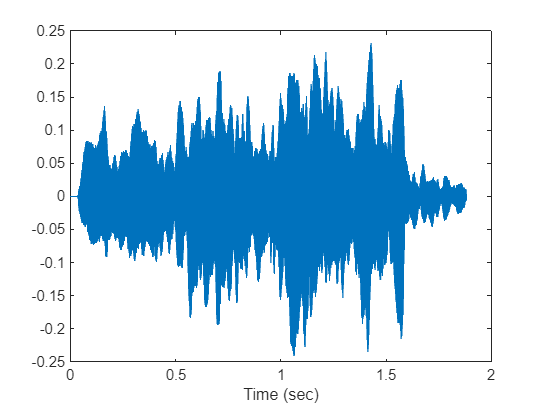

sound(y,Fs);

N=numel(y); Dt=1/fs; tj=Dt*(1:N)'; T=N*Dt; Dnu=1/T;

figure(1); plot(tj,y); xlabel('Time (sec)');

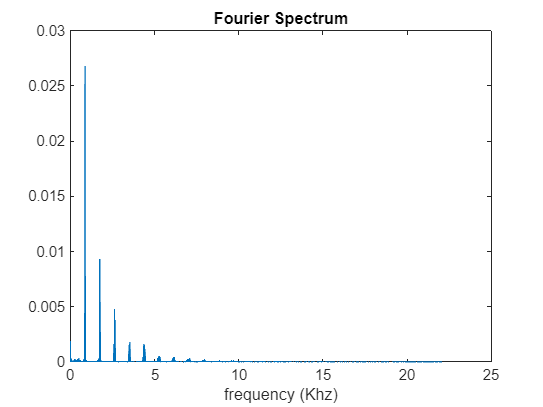


Y=fftshift(fft(y)); Y=[Y; Y(1)]*T/N;
nu=(-N/2:N/2)'/T;

m=N/2+1;

figure(2), plot(1e-3*nu(m:end),abs(Y(m:end))) %Khz
xlabel('frequency (Khz)'); title('Fourier Spectrum')


power = abs(Y(m:end)).^2;
%1st maximum
index=find(power == max(power));
note_Khz = nu(m+index)

note_Khz = 875.1519


display([note_Khz*1e-3])

    0.8752



Now with the file "guitarharmonic.wav"

[y,fs]=audioread('audio_files\guitarharmonic.wav')

y =    -0.0020
   -0.0010
    0.0005
    0.0008
   -0.0003
    0.0005
    0.0019
    0.0005
   -0.0005
   -0.0001


fs = 22050

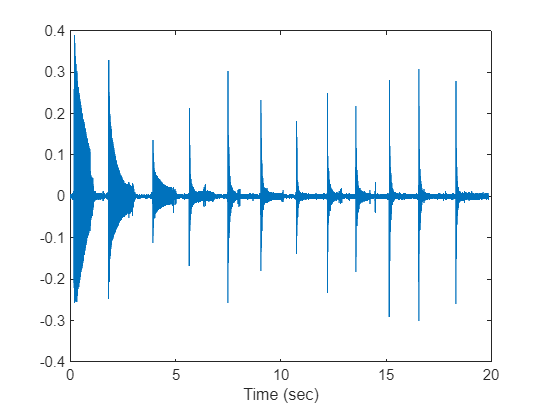

%sound(y,Fs);

N=numel(y); Dt=1/fs; tj=Dt*(1:N)'; T=N*Dt; Dnu=1/T;

figure(1); plot(tj,y); xlabel('Time (sec)');

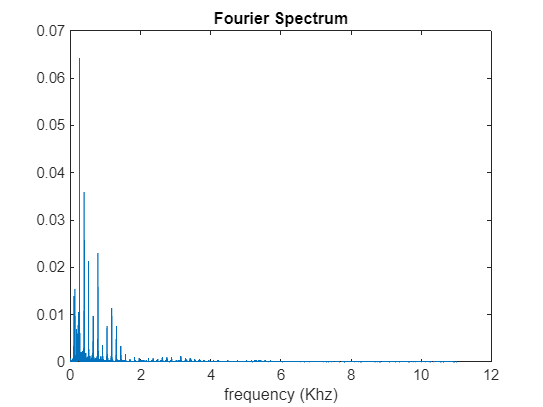


Y=fftshift(fft(y)); Y=[Y; Y(1)]*T/N;
nu=(-N/2:N/2)'/T;

m=N/2+1;

figure(2), plot(1e-3*nu(m:end),abs(Y(m:end))) %Khz
xlabel('frequency (Khz)'); title('Fourier Spectrum')


power = abs(Y(m:end)).^2;
%1st maximum
index=find(power == max(power));
note_Khz = nu(m+index)

note_Khz = 261.6656


display([note_Khz*1e-3]);

    0.2617



[y,fs]=audioread('audio_files\guitarharmonic.wav')

y =    -0.0020
   -0.0010
    0.0005
    0.0008
   -0.0003
    0.0005
    0.0019
    0.0005
   -0.0005
   -0.0001


fs = 22050


%%Plot only the second note;
tj=Dt*(1:N)';
nu=(-N/2:N/2)'/T;
Npart = 1:N/12:N %Create a partition

Npart =            1       36496       72991      109486      145981      182476      218971      255466      291961      328456      364951      401446


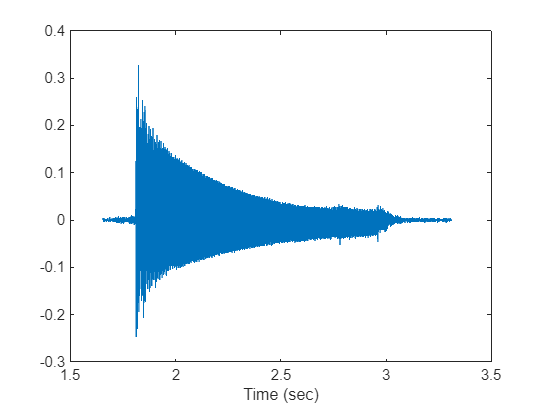


tj2 = tj(Npart(2):Npart(3)-1);
yj2 = y(Npart(2):Npart(3)-1);
figure(3); plot(tj2,yj2); xlabel('Time (sec)');

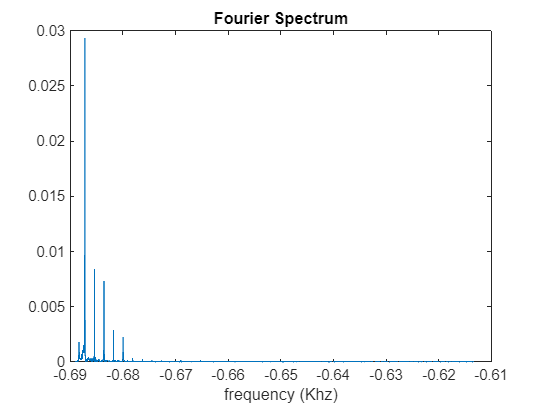


Yj2 = fftshift(fft(yj2));  Yj2=[Yj2; Yj2(1)]*T/N;
nuj2=(-N/2:N/2)'/T;


numPartitions=12;
partitionLength = floor(length(nu)/12)+1;
nu_partitions= zeros(12,partitionLength);
for i=1:numPartitions
    startIndex = (i-1)*partitionLength+1;
    if i==numPartitions
        endIndex=length(nu);
        last_partition=nu(end-partitionLength,end);
    else
        endIndex=i*partitionLength;
            nu_partitions(i,:) = nu(startIndex:endIndex);
    end
end


m=ceil(numel(Yj2)/2)+1;
numel(nuj2);
numel(Yj2);

clf; figure(3); 
plot(1e-3*nu_partitions(2,m:end),abs(Yj2(m:end))) %Khz
xlabel('frequency (Khz)'); title('Fourier Spectrum')


power = abs(Yj2(m:end)).^2;
%1st maximum
index=find(power == max(power));
note_Khz = nu_partitions(2,m+index)

note_Khz = -687.2394


display([note_Khz*1e-3]);

   -0.6872



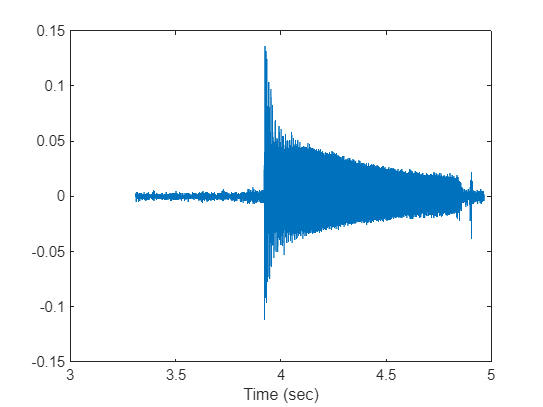

tj3 = tj(Npart(3):Npart(4)-1);
yj3 = y(Npart(3):Npart(4)-1);
figure(4); plot(tj3,yj3); xlabel('Time (sec)');

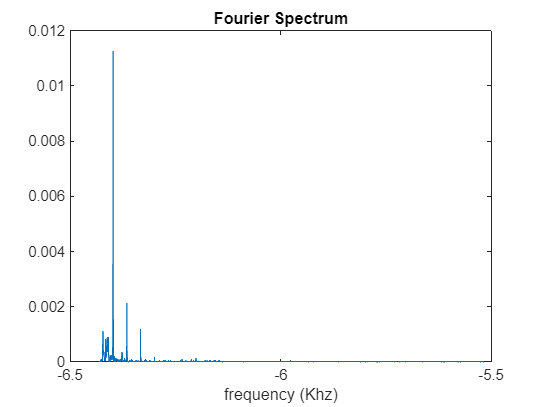


Yj3 = fftshift(fft(yj3));  Yj3=[Yj3; Yj3(1)]*T/N;
nuj3=(-N/2:N/2)'/T;

clf; figure(4); 
plot(1e-3*nu_partitions(3,m:end),abs(Yj3(m:end))) %Khz
xlabel('frequency (Khz)'); title('Fourier Spectrum')


power = abs(Yj3(m:end)).^2;
%1st maximum
index=find(power == max(power));
note_Khz = nu_partitions(3,m+index)

note_Khz = -6.3984e+03


display([note_Khz*1e-3]);

   -6.3984

